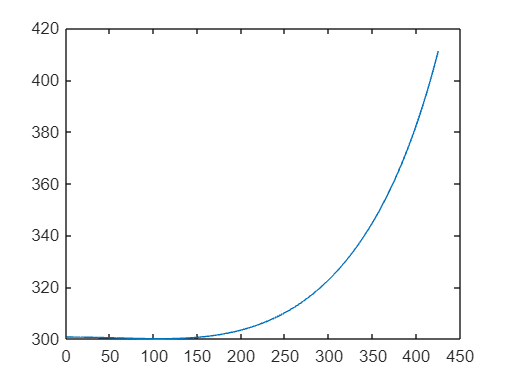

R = 300.4;

x1 = -R:0.00001:-0.0001;
for m=1:length(x1)
    %一个圆的下半部分的y坐标
    y1(m) = -sqrt(R^2-(x1(m))^2);
    %圆上的点到(0,300.716)的距离
    d1(m) = sqrt((x1(m))^2+(y1(m)+300.7160)^2);
    a = 1;
    b = -562.3748*y1(m)/x1(m);
    c = -169115.100357;
    x(m) = (-b-sqrt(b^2-4*a*c))/2;
    y(m) = x(m)*y1(m)/x1(m);
    d(m) = sqrt((x(m))^2+(y(m))^2);
end
plot(d1,d);
ZZZ = spline(d1,d);
save('ZZZ.mat', 'ZZZ');